# **Predict Behaviour from Ca2+ signal using Machine learning**

s = settings;
s.matlab.editor.AllowFigureAnimation.PersonalValue = true;

## Load experiment

% note : the experiment loaded here has been preprocessed for peak detection and
% rescaling. If this is not the case, you need to do it.
load('C:\Users\THE BEASTWO\Documents\MATLAB\arboreal_scans_final_new_zscored_compressed\2019-10-01_exp_1\2019-10-01_exp_1.mat')

# 1. SVM classifier using different predictors types and observations sets

## Example 1.1 : SVM classifier on running speed using peak magnitude

The model out-of-sample misclassification rate is 29.3%


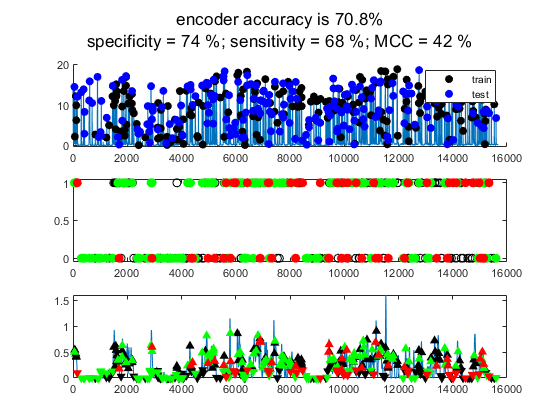

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, true, 'svm', 'peaks_rescaled',{'encoder'});

## Example 1.2 : SVM classifier on running speed using peak modulation

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, true, 'svm', 'peaks_subtracted',{'encoder'});

## Example 1.3 : SVM classifier on the Laser MI using peak modulation

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, true, 'svm', 'peaks_subtracted',{'laser'});

## Example 1.4 : SVM classifier on all metrics using peak modulation

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, true, 'svm', 'peaks_subtracted','');

## Example 1.5 : SVM classifier on all metrics using peak magnitude

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, true, 'svm', 'peaks_rescaled','');

# 2. SVM classifier using different predictors groupings

## Preprocessing : Get clusters, generate groups

% Step 1 : dimensionality reduction on modulated regions, asking for 6 PHATE
obj.get_dimensionality([], 'phate', 'peaks_subtracted', 6);

% Step 2 : dbscan clustering, auto epsilon (i.e. 95% of data assigned to a
% cluster)
obj.cluster_factors('dbscan', []); % can be pushed to a fixed number of clusters
% obj.cluster_factors('dbscan', -5);  % try to make 5 clusters

% Step 3 : get ROI indices for the clusters
groups = {};
for el = 1:obj.dimensionality.N_clust
    groups{el} = find(obj.dimensionality.cluster_idx == el);
end

## Example 2.1 : SVM classifier on running speed using modulation of averaged clusters

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, true, 'svm', 'peaks_subtracted',{'encoder'}, groups);

## Example 2.2 : SVM classifier on all metrics using modulation of averaged clusters

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, true, 'svm', 'peaks_subtracted','', groups);

## Example 2.3 : (slow) SVM classifier on all metrics using modulation of averaged clusters, multiple iterations

% Using the entire dendritic tree on the encoder
multirun = {};
parfor iter = 1:10
    multirun{iter} = predict_behaviours(obj, true, 'svm', 'peaks_subtracted','', groups, 'optimize_hyper', true, 'optimization_method', 'manual');iter
end
labels = reordercats(categorical(multirun{1}.beh_type),multirun{1}.beh_type);
scores = cell2mat(cellfun(@(x) cellfun(@(y) y(end), x.score)', multirun, 'UniformOutput', false));
figure();bar(labels, nanmean(scores,2));hold on;ylim([-10,50]);hold on;
errorbar(nanmean(scores,2), nanstd(scores,[], 2)./sqrt(size(scores, 2))),'ko';hold on;

# 3. SVM regression using different predictors and observations

## Example 3.1 : SVM regression on running speed using peak magnitude

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, false, 'svm', 'peaks_rescaled',{'encoder'});

## Example 3.2 : SVM regression on running speed using peak modulation

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, false, 'svm', 'peaks_subtracted',{'encoder'});

## Example 3.3 : SVM regression on the Laser MI using peak modulation

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, false, 'svm', 'peaks_subtracted',{'laser'});

## Example 3.4 : SVM regression on all metrics using peak modulation

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, false, 'svm', 'peaks_subtracted','');

## Example 3.5 : SVM regression on all metrics using peak magnitude

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, false, 'svm', 'peaks_rescaled','');

## Example 3.6 : (slow) SVM regression on all metrics using modulation of averaged clusters, multiple iterations

% Using the entire dendritic tree on the encoder
multirunR = {};
parfor iter = 1:10
    multirunR{iter} = predict_behaviours(obj, false, 'svm', 'peaks_subtracted','', groups,'optimize_hyper', true, 'optimization_method', 'manual');iter
end
labels = reordercats(categorical(multirunR{1}.beh_type),multirunR{1}.beh_type);
scores = cell2mat(cellfun(@(x) cellfun(@(y) y(end), x.score)', multirunR, 'UniformOutput', false));
figure();bar(labels, nanmean(scores,2));hold on;ylim([-10,50]);hold on;
errorbar(nanmean(scores,2), nanstd(scores,[], 2)./sqrt(size(scores, 2))),'ko';hold on;

# 4. Linear regression and linear classifier

svm fit is not the best solution high diemensional data. For those, using a linear regression model or or a linear classifier is more adpated  

## Example 4.1 : Linear classifier onselected metrics using modulation

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, true, 'linear', 'peaks_subtracted',{'encoder','trigger','BodyCam_L_whisker','laser'});

## Example 4.2 : Linear regression model on selected metrics using modulation

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'encoder','trigger','BodyCam_L_whisker','laser'});

## Example 4.3 : Linear classifier on selected metrics using modulation with hyperparameter tuning

The out-of-sample misclassification rate is 24.1%


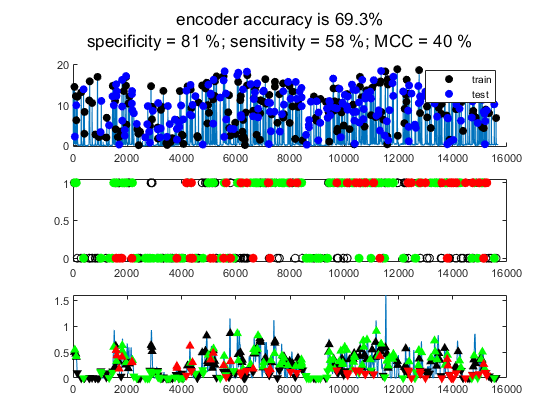

The out-of-sample misclassification rate is 27.1%


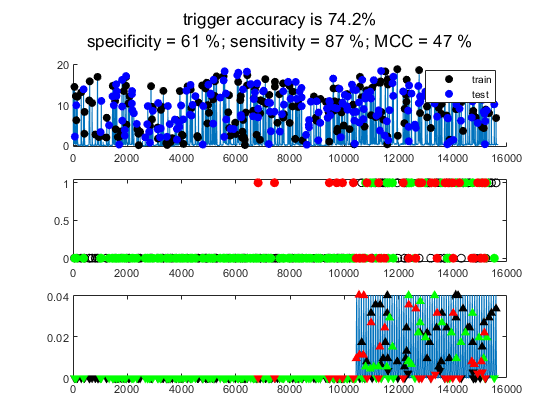

The out-of-sample misclassification rate is 18.1%


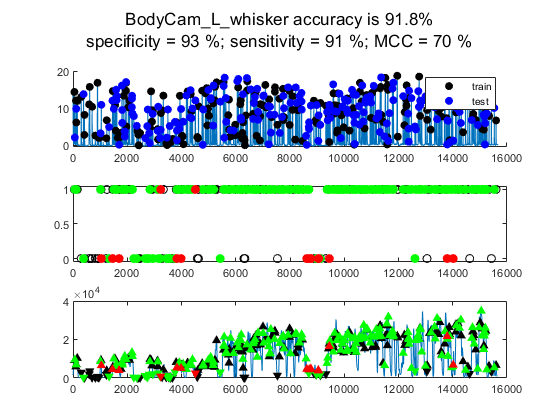

The out-of-sample misclassification rate is 33.6%


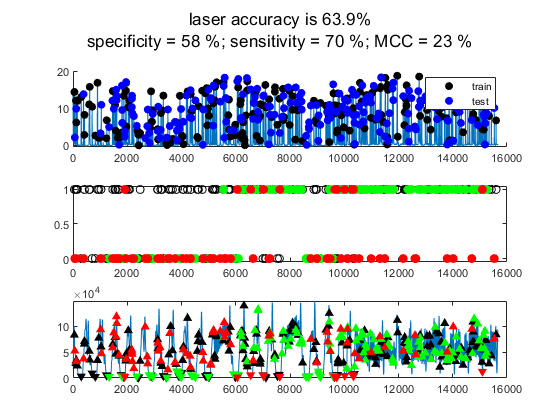

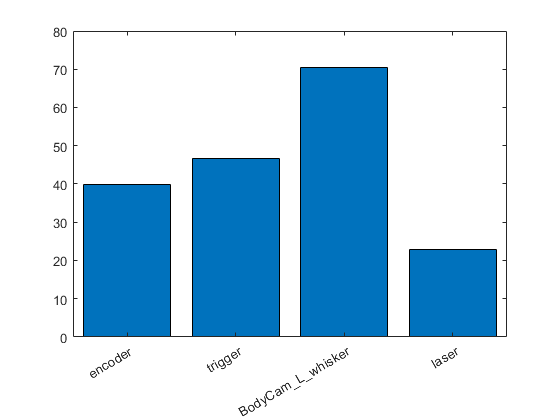

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, true, 'linear', 'peaks_subtracted',{'encoder','trigger','BodyCam_L_whisker','laser'}, '', 'optimize_hyper', true, 'optimization_method', 'manual');

## Example 4.4 : Linear regression model on selected metrics using modulation with hyperparameter tuning

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'encoder','RT3D_MC','trigger'}, '', 'optimize_hyper', true, 'optimization_method', 'manual');

## Example 4.5 : (slow) Linear regression model on selected metrics using modulation, multiple iterations

% Using the entire dendritic tree on the encoder
multirunRL = {};
parfor iter = 1:10
    multirunRL{iter} = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'encoder','RT3D_MC','trigger'}, '');iter
end
labels = reordercats(categorical(multirunRL{1}.beh_type),multirunRL{1}.beh_type);
scores = cell2mat(cellfun(@(x) cellfun(@(y) y(end), x.score)', multirunRL, 'UniformOutput', false));
figure();bar(labels, nanmean(scores,2));hold on;ylim([-10,100]);hold on;
errorbar(nanmean(scores,2), nanstd(scores,[], 2)./sqrt(size(scores, 2))),'ko';hold on;

## Example 4.6 : (slow) Linear regression model on selected metrics using magnitudes, multiple iterations

% Using the entire dendritic tree on the encoder
multirunRL = {};
parfor iter = 1:10
    multirunRL{iter} = predict_behaviours(obj, false, 'linear', 'peaks_rescaled',{'encoder','RT3D_MC','trigger'}, '');iter
end
labels = reordercats(categorical(multirunRL{1}.beh_type),multirunRL{1}.beh_type);
scores = cell2mat(cellfun(@(x) cellfun(@(y) y(end), x.score)', multirunRL, 'UniformOutput', false));
figure();bar(labels, nanmean(scores,2));hold on;ylim([-10,100]);hold on;
errorbar(nanmean(scores,2), nanstd(scores,[], 2)./sqrt(size(scores, 2))),'ko';hold on;

## Example 4.7 : (VERY slow) Linear regression model on selected metrics using magnitudes, multiple iterations with hyperparameter tuning

% Using the entire dendritic tree on the encoder
multirunRL = {};
for iter = 1:10
    multirunRL{iter} = predict_behaviours(obj, false, 'linear', 'peaks_rescaled','', '','optimize_hyper', true, 'optimization_method', 'manual');iter
end
labels = reordercats(categorical(multirunRL{1}.beh_type),multirunRL{1}.beh_type);
scores = cell2mat(cellfun(@(x) cellfun(@(y) y(end), x.score)', multirunRL, 'UniformOutput', false));
figure();bar(labels, nanmean(scores,2));hold on;ylim([-10,100]);hold on;
errorbar(nanmean(scores,2), nanstd(scores,[], 2)./sqrt(size(scores, 2))),'ko';hold on;

# 5. Linear regression on groups vs ROIS

## Example 5.1 : Linear classifier on whisking using modulation. Predictors are all ROIs

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'BodyCam_L_whisker'}, '');

## Example 5.2 : Linear classifier on whisking using modulation. Predictors are all groups

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'BodyCam_L_whisker'}, groups);

## Example 5.3 : Linear classifier on whisking using modulation. Predictors are all groups

% Using the entire dendritic tree on the encoder
out = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'BodyCam_L_whisker'}, obj.ref.indices.somatic_ROIs);

## Example 5.4 : Linear classifier on whisking using modulation. Predictors are ROIs of each groups

% Using the entire dendritic tree on the encoder
multirungp = {};
for iter = 1:numel(groups)
    multirungp{iter} = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'BodyCam_L_whisker'}, groups{iter});
end
gp_names = [strcat('group ', strsplit(num2str(1:numel(groups)),' '))];
labels = reordercats(categorical(gp_names),gp_names);
scores = cell2mat(cellfun(@(x) cellfun(@(y) y(end), x.score)', multirungp, 'UniformOutput', false));
figure();bar(labels, scores);hold on;ylim([-10,100]);hold on;
